data = load("resultadosCSV_3M.txt");
length(data)

ans = 4096


stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

load('DatosCalibracion.mat');
T           = 1/(300e6)

T = 3.3333e-09


T_buscado = 1/(2*3.3e6)

T_buscado = 1.5152e-07

fino_buscado = T_buscado - 45*T

fino_buscado = 1.5152e-09

T_buscado/T

ans = 45.4545

t_fino = cal_start(start) - cal_stop(stop)

t_fino = 	1.0e+-8 *

   -0.1447   -0.1476   -0.1458   -0.1435    0.1864    0.1886    0.1876    0.1890    0.1875   -0.1445   -0.1447   -0.1469   -0.1480   -0.1458   -0.1435    0.1864    0.1846    0.1884    0.1869    0.1875   -0.1445   -0.1447   -0.1423   -0.1447   -0.1497   -0.1435    0.1870    0.1857    0.1896    0.1889    0.1859   -0.1443   -0.1487   -0.1469   -0.1472   -0.1443   -0.1468    0.1852    0.1857    0.1848    0.1859    0.1859   -0.1443   -0.1487   -0.1469   -0.1455   -0.1497   -0.1435    0.1864    0.1830


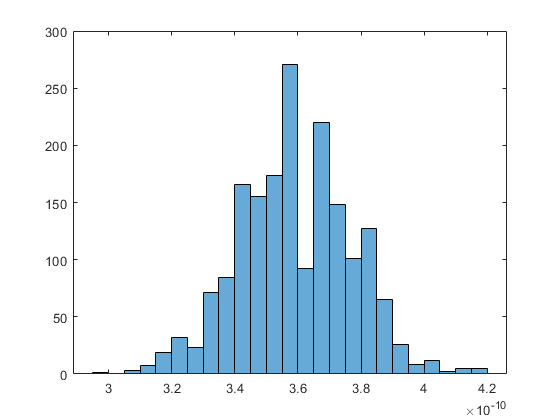

% t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(t_fino(t_fino>0)-fino_buscado)


%en freq
t_fino

t_fino = 	1.0e+-8 *

   -0.1447   -0.1476   -0.1458   -0.1435    0.1864    0.1886    0.1876    0.1890    0.1875   -0.1445   -0.1447   -0.1469   -0.1480   -0.1458   -0.1435    0.1864    0.1846    0.1884    0.1869    0.1875   -0.1445   -0.1447   -0.1423   -0.1447   -0.1497   -0.1435    0.1870    0.1857    0.1896    0.1889    0.1859   -0.1443   -0.1487   -0.1469   -0.1472   -0.1443   -0.1468    0.1852    0.1857    0.1848    0.1859    0.1859   -0.1443   -0.1487   -0.1469   -0.1455   -0.1497   -0.1435    0.1864    0.1830


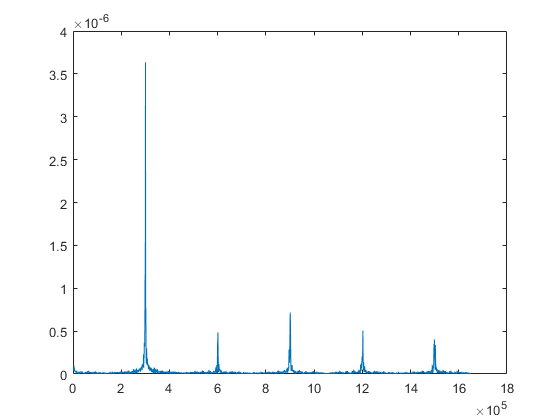

f_t = fft(t_fino(1,:).*hanning(1, 1024));
f = linspace(0, 3.3e6, 4096);
plot(f(1:end/2), abs(f_t(1:end/2)));

% y = filtfilt(Num, 1, t_fino(1, :));
% f_t = fft(y);
% f = linspace(0, 3.3e6, 4096);
% plot(f(1:end/2), abs(f_t(1:end/2)));
% x = ifft(f_t);
% histogram(x, 100)

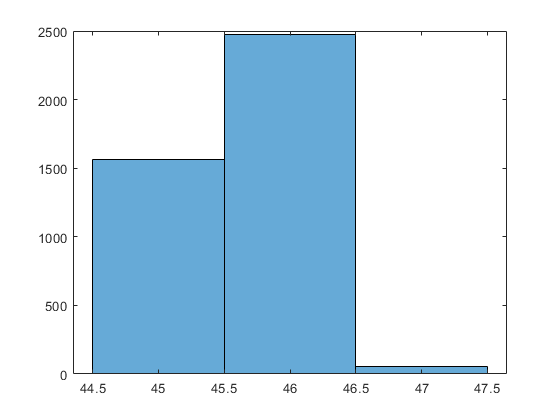


histogram(coarse)

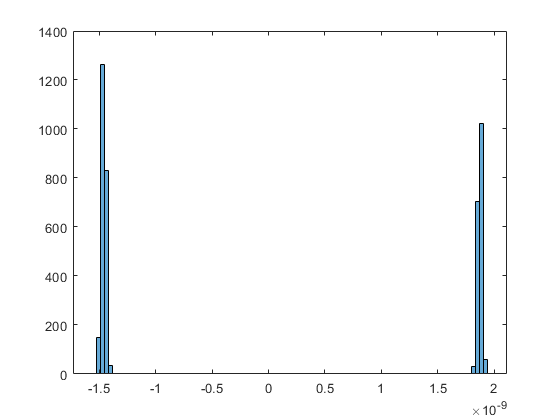

histogram(t_fino,100)

t_pos = t_fino(t_fino>0)

t_pos = 	1.0e+-8 *

    0.1864    0.1886    0.1876    0.1890    0.1875    0.1864    0.1846    0.1884    0.1869    0.1875    0.1870    0.1857    0.1896    0.1889    0.1859    0.1852    0.1857    0.1848    0.1859    0.1859    0.1864    0.1830    0.1876    0.1890    0.1865    0.1836    0.1868    0.1884    0.1839    0.1899    0.1899    0.1868    0.1884    0.1869    0.1838    0.1871    0.1864    0.1876    0.1869    0.1875    0.1864    0.1812    0.1851    0.1890    0.1875    0.1836    0.1868    0.1826    0.1869    0.1882


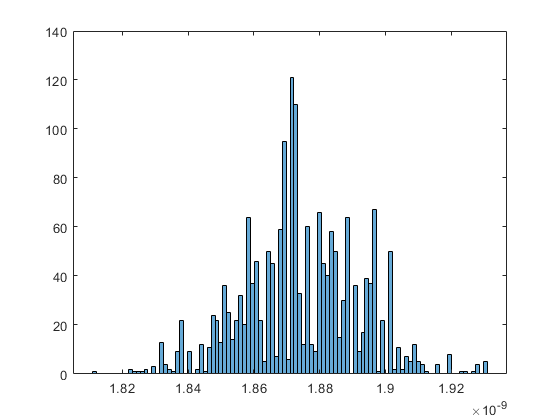

histogram(t_pos, 100)

std(t_pos)

ans = 1.7783e-11

t_neg = t_fino(t_fino<0)

t_neg = 	1.0e+-8 *

   -0.1447   -0.1476   -0.1458   -0.1435   -0.1445   -0.1447   -0.1469   -0.1480   -0.1458   -0.1435   -0.1445   -0.1447   -0.1423   -0.1447   -0.1497   -0.1435   -0.1443   -0.1487   -0.1469   -0.1472   -0.1443   -0.1468   -0.1443   -0.1487   -0.1469   -0.1455   -0.1497   -0.1435   -0.1445   -0.1476   -0.1483   -0.1447   -0.1488   -0.1464   -0.1465   -0.1458   -0.1447   -0.1484   -0.1455   -0.1464   -0.1465   -0.1458   -0.1454   -0.1454   -0.1426   -0.1464   -0.1477   -0.1447   -0.1423   -0.1480


std(t_neg)

ans = 1.9080e-11

media = mean(t_fino(t_fino>0))

media = 1.8741e-09

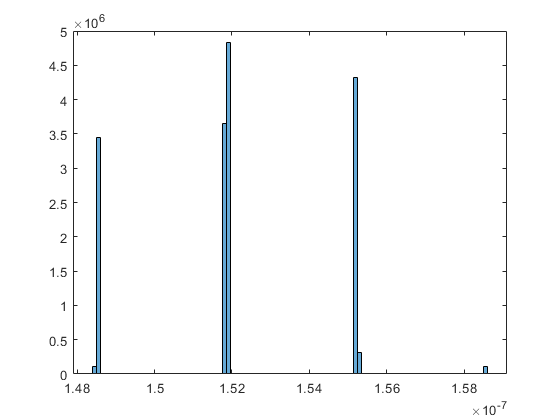

histogram(t,100)

% T_buscado - 1.518e-7


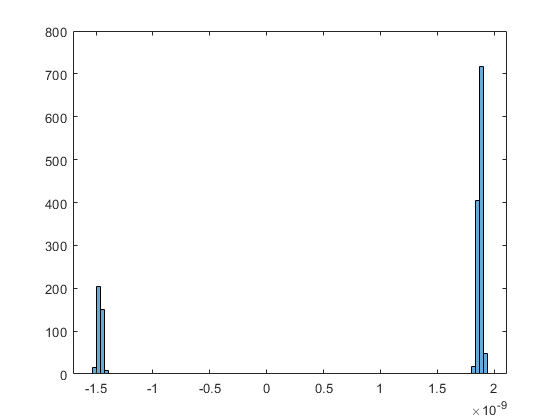

%%46 cuentas son las correctas
indices_45 = find(coarse==45);
indices_46 = find(coarse==46);
indices_47 = find(coarse==47);

%%45 cuentas
start_45 = start(indices_45);
stop_45 = stop(indices_45);
st_45 = start_45 - stop_45;
tiempo_45 = cal_start(start_45) - cal_stop(stop_45);
histogram(tiempo_45, 100)

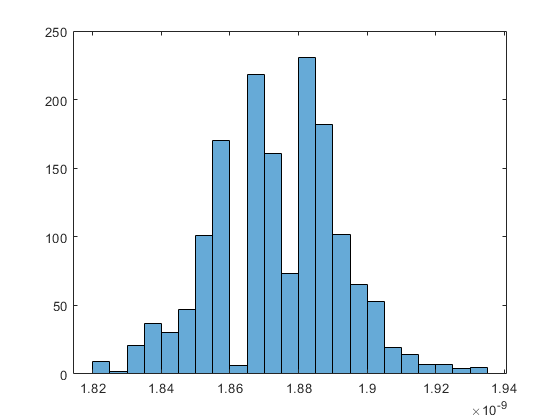

tiempo_45_corregido = [tiempo_45(tiempo_45<0)+T, tiempo_45(tiempo_45>0)];
histogram(tiempo_45_corregido)

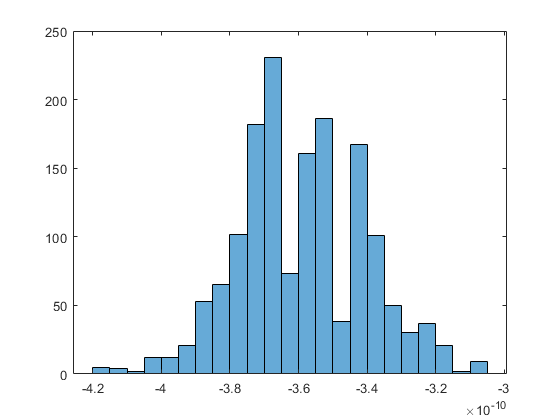

histogram((T_buscado - 45*T - tiempo_45_corregido))

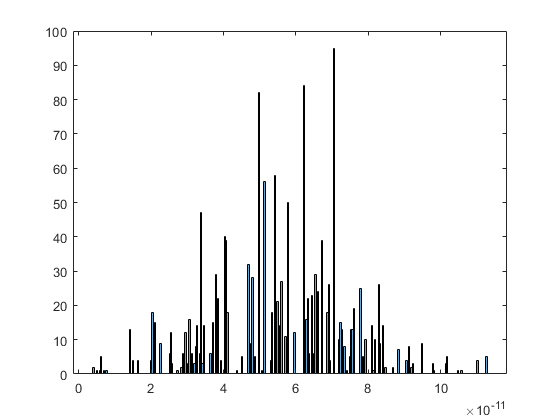

fino_buscado_45 = T_buscado - (46*T - tiempo_45_corregido);
histogram(fino_buscado_45, 300)


%%46 grueso
start_46 = start(indices_46);
stop_46  = stop(indices_46);
tiempo_46 = cal_start(start_46) - cal_stop(stop_46);
tiempo_46_corregido = [tiempo_46(tiempo_46>0), tiempo_46(tiempo_46<0)+T];
fino_buscado_46 = T_buscado - (46*T - tiempo_46_corregido)

fino_buscado_46 = 	1.0e+-9 *

    0.0461    0.0673    0.0461    0.0280    0.0522    0.0385    0.0335    0.0385    0.0461    0.0115    0.0183    0.0496    0.0809    0.0496    0.0531    0.0458    0.0461   -0.0063    0.0183    0.0496    0.0531    0.0496    0.0531    0.0496    0.0183    0.0280    0.0461    0.0385    0.0335    0.0784    0.0522    0.0385    0.0586    0.0784    0.0335    0.0601    0.0335    0.0385    0.0522    0.0784    0.0461    0.0567    0.0461    0.0458    0.0461    0.0673    0.0183    0.0496    0.0531    0.0496


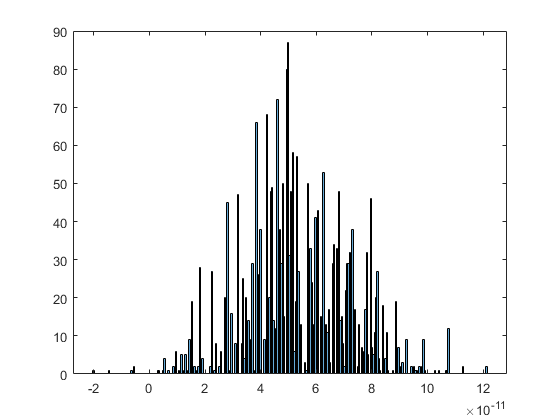

histogram(fino_buscado_46, 300)


%%47 grues0
fino_buscado_47 = T_buscado - (47)*T 

fino_buscado_47 = -5.1515e-09

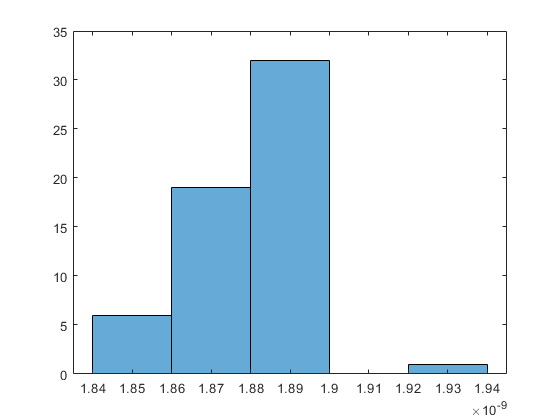

start_47 = start(indices_47);
stop_47  = stop(indices_47);
tiempo_47 = cal_start(start_47) - cal_stop(stop_47);
histogram(tiempo_47)

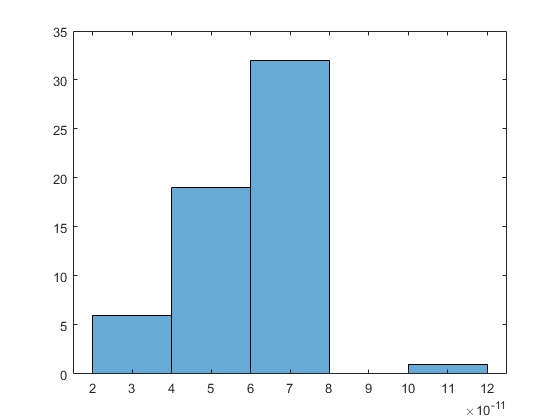

fino_buscado_47 = T_buscado - (46*T - tiempo_47);
histogram(fino_buscado_47)

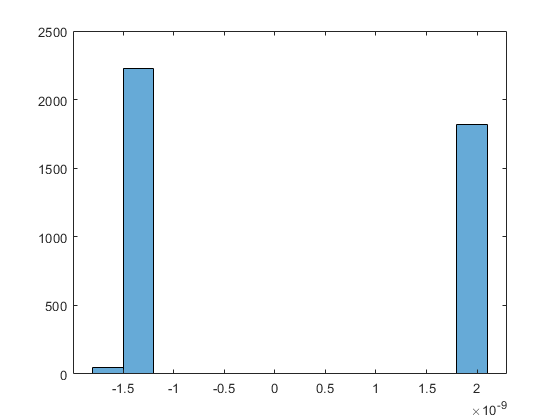


%%pruebas
finos_generales = cal_start(start) - cal_stop(stop);
histogram(finos_generales)

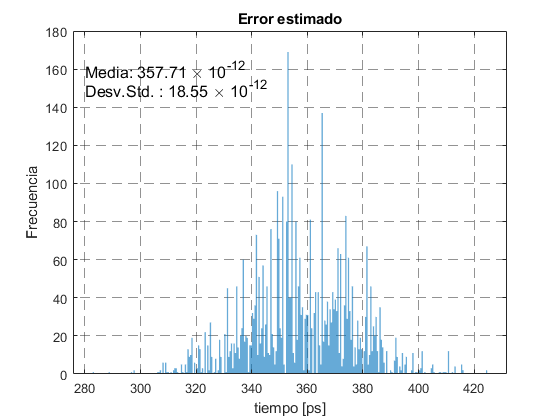

%%Histograma final
y_final = [t_fino(t_fino>0)-fino_buscado, T+t_fino(t_fino<0)-fino_buscado];
h = histogram(y_final*1e12, 300);
% Customize the appearance
h.FaceColor = '#0072BD';    % Set the bar color
h.EdgeColor = 'none';       % Remove the edges of the bars
grid on;
set(gca, 'GridLineStyle', '--', 'GridAlpha', 0.5);
xlabel('tiempo [ps]'); ylabel('Frecuencia'); title('Error estimado');
% Calculate statistics

%Adjust values to show in e-12 scale
mean_val_e12 = mean(y_final) / 1e-12;
std_val_e12 = std(y_final) / 1e-12;
% Add text annotations, forcing e-12 notation
text(280, 160, sprintf('Media: %.2f \\times 10^{-12}', mean_val_e12), 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');
text(280, 150, sprintf('Desv.Std. : %.2f \\times 10^{-12}', std_val_e12), 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');

exportgraphics(gcf,'Medicion_final.eps');

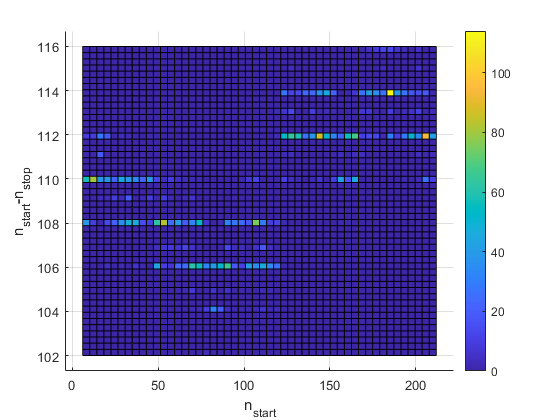

st = start-stop;
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (maxbin_start-minbin_start);
% std(st_positivo)
hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_3M3.eps');

tiempos_45_buenos = cal_start(start_45(st_45>0))-cal_stop(stop_45(st_45>0))

tiempos_45_buenos = 	1.0e+-8 *

    0.1876    0.1890    0.1875    0.1884    0.1869    0.1875    0.1896    0.1889    0.1859    0.1848    0.1859    0.1859    0.1876    0.1890    0.1865    0.1884    0.1839    0.1899    0.1884    0.1869    0.1838    0.1876    0.1869    0.1875    0.1851    0.1890    0.1875    0.1826    0.1869    0.1882    0.1884    0.1839    0.1865    0.1858    0.1869    0.1882    0.1851    0.1869    0.1865    0.1896    0.1859    0.1909    0.1848    0.1893    0.1859    0.1896    0.1884    0.1901    0.1896    0.1884


histogram(tiempos, 100);

Unrecognized function or variable 'tiempos'.

fino_buscado = 1/(2*3.3e6) - 46*T
mean_fino = mean(tiempos)
error = fino_buscado - mean_fino
std(tiempos)

clf;
y = [fino_30_buenos; fino_30_malos+T; fino_31_buenos+T; fino_31_malos];
histogram(y)
presicion = std(y)
media     = mean(y)
coarse_correcto = 30;
N = 100;
length(y)
length(fino_30_malos)
length(fino_31_buenos)

% Preallocate arrays for bin edges and counts
binEdges = [];
counts = zeros(4, N);  % Assuming there are 4 data vectors

% Calculate histograms
%%cuidado acá! los finos_31 deberían dar una medición fina negativa (~-3)
%%pero sumo T a los buenos y nada a los malos para hacerlos positivos, y
%%juntarlos con las mediciones buenas
data = {fino_30_buenos, (fino_30_malos+T), fino_31_buenos+T, fino_31_malos};
for i = 1:4
    h = histogram(data{i}, N, 'Visible', 'off');
    binEdges = h.BinEdges;
    counts(i, :) = h.BinCounts;
end

% Create common bin edges
commonEdges = linspace(min(binEdges), max(binEdges), N+1);

% Recalculate counts using common edges
for i = 1:4
    counts(i, :) = histcounts(data{i}, commonEdges);
end

% Combine the counts into a matrix
countsMatrix = counts';

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo[s]');
ylabel('Frecuencia ');
legend({'Fino 30', 'Fino 30(*)', 'Fino 31', 'Fino 31(*)'});
% title('Stacked Histogram of Different Data Groups');
exportgraphics(gcf,'histograma_3M3.eps');
fino_buscado = T_buscado - 30*T
error = 30*T + media - T_buscado

clf;

% Data vectors
data = {coarse_30_buenos, coarse_30_malos, coarse_31_buenos, coarse_31_malos};

% Number of bins
N = 8;

% Create common bin edges
commonEdges = 29.5:0.25:31.5

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({'Grueso 30', 'Grueso 30(*)', 'Grueso 31', 'Grueso 31(*)'});
exportgraphics(gcf,'histograma_coarse_3M3.eps');